# Perceptrón multicapa

El objetivo de esta práctica es la implementación del perceptrón multicapa (MLP: *multilayer perceptron*), una red neural capaz de capturar la relación no lineal entre dos conjuntos.

El MLP es una extensión del perceptrón, que incluye una o mas capas de neuronas entre el input y el output. Las neuronas de las capas intermedias (u ocultas) tienen normalmente una función de activación no lineal (sigmoidal, o tangente hiperbólica) mientras que las neuronas de la capa de salida tienen normalmente función de activación lineal o sigmoide, dependiendo del tipo de tarea que se quiera solucionar (regresión o clasificación).

Se probará primero el programa con datos sintéticos (apartado 1) y luego se aplicará el MLP a un problema real (apartado 2).

## 1. Datos sintéticos

## 1.1 REGRESIÓN

**1.1.1 Datos**

Vamos a generar un conjunto de datos de entrada muestreando de manera aleatoria y uniforme el rango [0, 1]. Estos serán los datos o patrones de input a la red. Para crear los target de entrenamiento (conjunto de respuestas correctas), se aplicará a estos datos una función de ruido del tipo:

donde x es un patrón de input y $\Gamma$ es ruido Gaussiano con media 0 y desviación estándar 0.3 (crearemos el ruido como hicimos en la práctica 2). Recordad que, como en la práctica anterior, habrá que separar los datos en un conjunto de entrenamiento y uno de validación usando la función` train_val_set.m`. Cread un dataset sintético (data y target) de manera parecida a lo hecho en la práctica 2 y visualizadlo. 

Propiedades del dataset:

- cada fila es un patrón diferente, hay **pattern_num **filas o patrones

- las columnas son las variables en esos datos (solo tenemos una)

- la última columna son los targets: $f(x) = 3x + sin(2\pi x) + 2 + \Gamma$

- añadimos ruido gaussiano para complicar el aprendizaje a la red (y experimentar con algo más realista) 

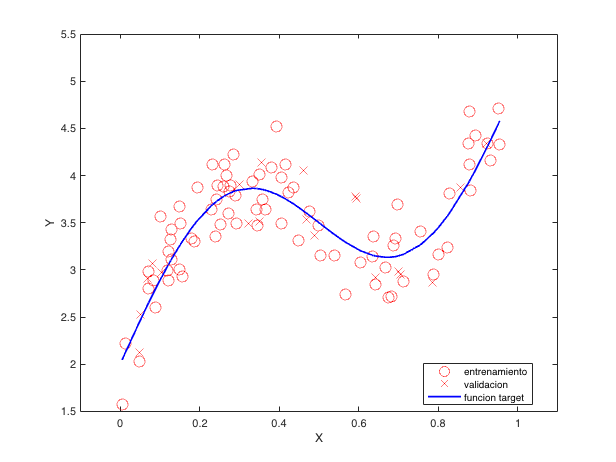

clear
close all

% INPUT
num_pattern = 100;
x = rand(1,num_pattern); % input (num_pattern puntos que toman valores entre 0 y 1 siguiendo una distribucion uniforme de probabilidad)
               % (vector fila)
X = [ones(1,num_pattern); x]; % añade una fila de unos a los inputs para tener:
                             % X =  1  1  1  ...
                             %      x1 x2 x3 ...
% RUIDO
sigmaG = 0.3 ; % desviacion tipica
G = randn(size(x))*sigmaG; % ruido gaussiano

% TARGET
Y = 3*x + sin(2*pi*x) + 2 + G;

% TRAINING AND VALIDATION SET
% Completa la función train_val_set
fracc = 0.8;
[Xtrain, Ytrain, Xval, Yval] = train_val_set(X,Y,fracc); % aquí preparamos el trainset y el testset

%% NO MODIFICAR -----------------------------------------------------
% Visualizamos el conjunto de entrenamiento
figure(1)
cla
set(gcf,'name','conjunto de entrenamiento')
plot(Xtrain(2,:), Ytrain, 'ro', 'linestyle', 'none', 'markersize', 10)
hold on
plot(Xval(2,:), Yval, 'rx', 'linestyle', 'none', 'markersize', 10)
[dummy, sortedIdx] = sort(Xtrain(2,:));
x2plot = Xtrain(2,sortedIdx);
plot(x2plot, 3*x2plot+sin(2*pi*x2plot)+2, 'b','linewidth', 1.5)
set(gca, 'fontsize', 10)
xlim([-0.1 1.1]), ylim([1.5 5.5])
xlabel('X')
ylabel('Y')
legend({'entrenamiento','validacion','funcion target'},'location','best')

**1.1.2 Test gradiente**

 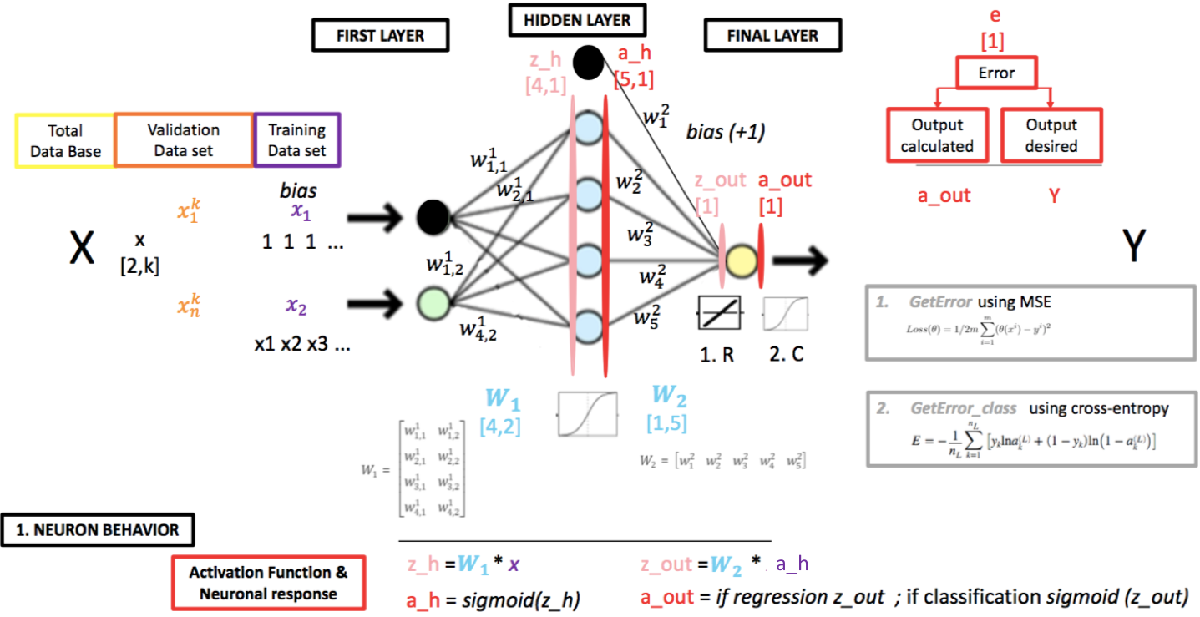

En este apartado vamos a implementar las funciones necesarias para obtener el gradiente por backpropagation (`gradientNN`) usando los datos del training (X y Y). Una vez completadas dichas funciones nos aseguraremos que nuestra implementación es correcta comparándola con una aproximación numérica del gradiente (la diferencia entre ambos métodos para el gradiente debería ser muy pequeña). 

Para simplificar los cálculos tomaremos como definición del error (cross-entropy): $E=\frac{1}{2n_L }\sum_{k=1}^{n_L } {\left(a_k^{\left(L\right)} -Y_k \right)}^2$, donde $n_L$ es el número de neuronas en la capa de salida.

Para este apartado asegúrate de:

- definir unos pesos iniciales `W1` y `W2` aleatorios a partir de una distribución normal de media 0 y desviación 0.1 (ojo con las dimensiones de W1 y W2)

       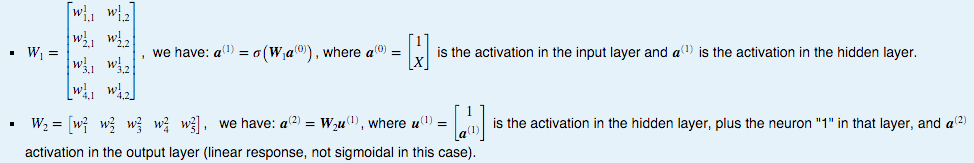

- implementar una función `sigmoid` que calcule la respuesta de la sigmoide

- implementar una función `sigmoidGradient` que calcule la respuesta de la derivada de la sigmoide

- implementar la función `gradientNN` que calcule el gradiente por backpropagation para una muestra

% Define unos parametros cualquiera para la red
hidden_units = 4; % numero de neuronas de la capa oculta
W1 = 0.1*randn(4,2); % pesos de la capa 1 (con 4 hidden units, y 2 inputs units)
W2 = 0.1*randn(1,5); % pesos de la capa 2 (con 5 hidden units (4 + bias), y 1 ouputs units)

%% NO MODIFICAR ------------------------------------------------------------------
% Por cada patron calculamos la diferencia entre el gradiente por backprop y el gradiente numerico
differ = zeros(size(Xtrain,2),1);
for p = 1:size(Xtrain,2)
    [DW1, DW2] = gradientNN(W1, W2, Xtrain(:,p), Ytrain(p)); 
    ww1 = W1'; ww2 = W2';
    WW = [ww1(:); ww2(:)]; % Juntamos todos los pesos en un vector
    % Calculamos el gradiente mediante el metodo numerico
    numDWW = numGradient(WW, hidden_units, Xtrain(:,p)', Ytrain(p)');
    dww1 = DW1'; dww2 = DW2';
    DWW = [dww1(:); dww2(:)];  % Juntamos todos los valores del gradiente en un vector
    differ(p) = norm(numDWW - DWW);
end
display(['La diferencia entre el gradiente por backprop y el gradiente numerico es de: ' num2str(mean(differ)) ' +/- ' num2str(std(differ))])

La diferencia entre el gradiente por backprop y el gradiente numerico es de: 7.4239e-11 +/- 1.8609e-11


**1.1.3 Aprendizaje del MLP - paralelo (batch)**

Una vez tengamos implementada la función para el cálculo del gradiente por backpropagation crearemos la función de aprendizaje de la red. En primer lugar aplicaremos un método en parelelo o batch, como hicimos en el descenso del gradiente de la práctica anterior (podéis tomar como modelo `descensoGradiente.m`). Para ello escribiremos la función `learningNN_paral.m `teniendo en cuenta lo siguiente:

- hemos de definir los parámetros del MLP: `max_iter`, alpha y `hidden units`

- implementar la función **GetError**`.m` que calcule el error a la salida de la red usando el error cuadrático medio.

- al principio de `learningNN_paral.m` habrá que inicializar los valores de los pesos **W1** y **W2** como hemos hecho en el apartado anterior (utilizad una desviación estándar de 5 ahora). 

- usaremos un bucle `for` para las iteraciones (como en la práctica 2) y otro bucle for para recorrer todos los patrones en cada iteración.

- al final de la función tendremos que calcular el error de entrenamiento y el error de validación usando `GetError.m`, como hacíamos en la práctica 2

El número de neuronas ocultas determina la capacidad de la red: si son muy pocas puede que la red no sea bastante flexible para aprender (underfitting), si son demasiadas la red puede aprender la estructura del ruido (overfitting).

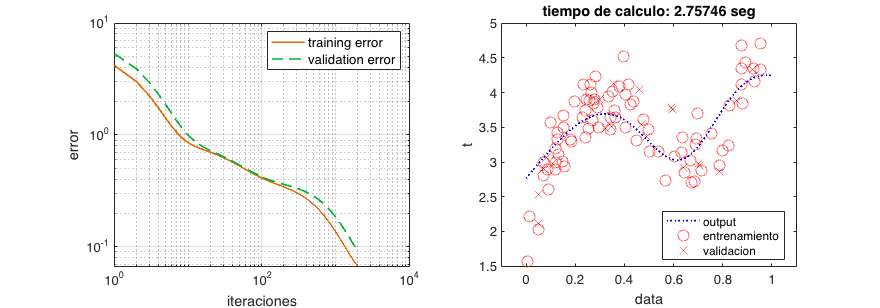

hidden_units = 40; % numero de neuronas en la capa oculta
max_iter = 2000;
alpha = 0.01;

[E_paral, E_val_paral, W1_paral, W2_paral,ct] = learningNN_paral(Xtrain, Ytrain, Xval, Yval, hidden_units, alpha, max_iter);

% Salida de la red
in = linspace(0,1,100);
in = [ones(size(in));in];
y = zeros(size(in,2),1);

for p = 1:size(in,2)  % pattern loop       
    x = in(:,p); % entrada para la muestra p
    % calcula activacion para las neuronas ocultas:
    z_h = W1_paral*x ;  % suma antes de la sigmoide
    a_h = sigmoid(z_h);  % activación de las neuronas ocultas
    a_h = [1; a_h];  % agrega la neurona cuyo valor es siempre igual a uno y que sirve de sesgo a la siguiente capa

    % calcula activacion de la neurona de salida:
    z_out = W2_paral*a_h ;  % suma antes de la función de respuesta de la neurona de salida
    y(p) = z_out;  % calcula respuesta neurona de salida (regresion: identidad -- clasificacion: sigmoide logistica)  
end   

    

% NO MODIFICAR -----------------------------------------
% Visualizacion del error y la salida de la red
figure(2)
plotOutputNN(Xtrain',Ytrain',Xval',Yval',in',y,E_paral,E_val_paral); 
title(sprintf('tiempo de calculo: %g seg',ct))

**1.1.4 Aprendizaje del MLP - serie (estocástico)**

Ahora vamos a modificar la función anterior para usar un método de actualización de los pesos en serie. Copia el código de `learningNN_paral` en `learningNN_serial` y modifícalo para que ahora los pesos `W1` y `W2` se actualicen para cada patrón con los valores de su gradiente (en lugar de utilizar la media como hemos hecho hasta ahora). Una vez hecho, añade las líneas de código necesarias para desordenar los patrones de manera aleatoria en cada iteración, implementando así el gradiente estocástico. 

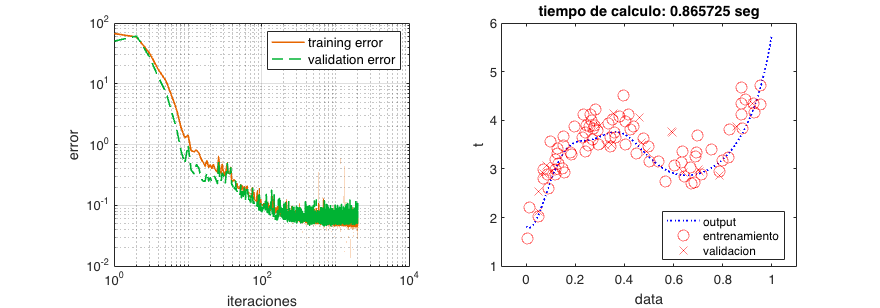


hidden_units = 40; % numero de neuronas en la capa oculta
max_iter = 2000;
alpha = 0.01;

[E_serial, E_val_serial, W1_serial, W2_serial,ct] = learningNN_serial(Xtrain, Ytrain, Xval, Yval, hidden_units, alpha, max_iter);

% Salida de la red
in = linspace(0,1,100);
in = [ones(size(in));in];
y = zeros(size(in,2),1);

for p = 1:size(in,2)  % pattern loop       
    x = in(:,p); % entrada para la muestra p
    % calcula activacion para las neuronas ocultas:
    z_h = W1_serial*x ;  % suma antes de la sigmoide
    a_h = sigmoid(z_h);  % activación de las neuronas ocultas
    a_h = [ones(size(y(p))); a_h];  % agrega la neurona cuyo valor es siempre igual a uno y que sirve de sesgo a la siguiente capa

    % calcula activacion de la neurona de salida:
    z_out = W2_serial*a_h ;  % suma antes de la función de respuesta de la neurona de salida
    y(p) = z_out;  % calcula respuesta neurona de salida (regresion: identidad -- clasificacion: sigmoide logistica)  
end   

    

% NO MODIFICAR -----------------------------------------
% Visualizacion del error y la salida de la red
figure(3)
plotOutputNN(Xtrain',Ytrain',Xval',Yval',in',y,E_serial,E_val_serial); 
title(sprintf('tiempo de calculo: %g seg',ct))

Comenta la figura 3 con respecto a la figura 2: ¿Qué método alcanza un mejor comportamiento en menos iteraciones? Incrementa num_pattern y comenta:

**Comentario:**

L'aprenentatge estocastic al principi va molt be pero a mesura que disminueix l'error tarda més. Això és degut a que abança bastant aleatoriament. En canvi el paral·lel és molt més directe. 

**1.1.4 Estudio de parámetros**

Para estudiar el efecto de los parámetros elegidos en la red, copia dos veces el código de la sección 1.1.3 y varía alpha y `hidden_units` para tratar de mostrar un caso de underfitting y uno de overfitting (es posible que tengas que lanzar el código más de una vez). Comenta los resultados explicando cómo varían en función de dichos parámetros.

*Underfitting:*

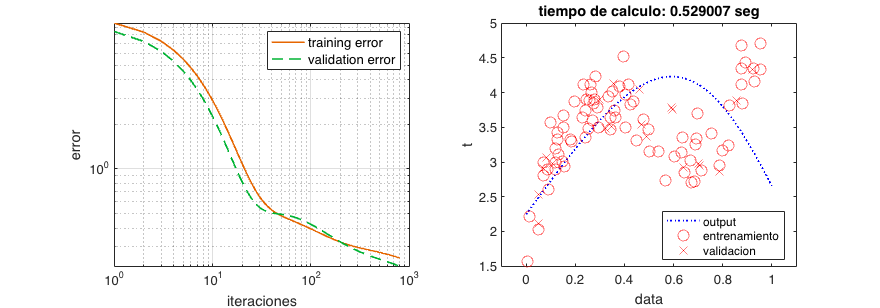

hidden_units = 4; % numero de neuronas en la capa oculta
max_iter = 800;
alpha = 0.01;

[E_paral, E_val_paral, W1_paral, W2_paral,ct] = learningNN_paral(Xtrain, Ytrain, Xval, Yval, hidden_units, alpha, max_iter);

% Salida de la red
in = linspace(0,1,100);
in = [ones(size(in));in];
y = zeros(size(in,2),1);

for p = 1:size(in,2)  % pattern loop       
    x = in(:,p); % entrada para la muestra p
    % calcula activacion para las neuronas ocultas:
    z_h = W1_paral*x ;  % suma antes de la sigmoide
    a_h = sigmoid(z_h);  % activación de las neuronas ocultas
    a_h = [1; a_h];  % agrega la neurona cuyo valor es siempre igual a uno y que sirve de sesgo a la siguiente capa

    % calcula activacion de la neurona de salida:
    z_out = W2_paral*a_h ;  % suma antes de la función de respuesta de la neurona de salida
    y(p) = z_out;  % calcula respuesta neurona de salida (regresion: identidad -- clasificacion: sigmoide logistica)  
end   

    

% NO MODIFICAR -----------------------------------------
% Visualizacion del error y la salida de la red
figure(2)
plotOutputNN(Xtrain',Ytrain',Xval',Yval',in',y,E_paral,E_val_paral); 
title(sprintf('tiempo de calculo: %g seg',ct))

*Overfitting:*

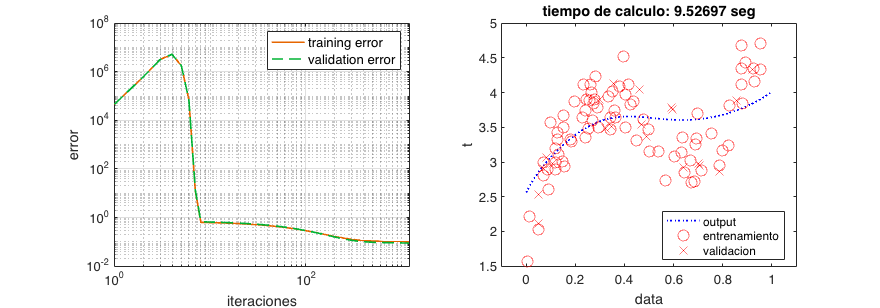

hidden_units = 800; % numero de neuronas en la capa oculta
max_iter = 1200;
alpha = 0.01;

[E_paral, E_val_paral, W1_paral, W2_paral,ct] = learningNN_paral(Xtrain, Ytrain, Xval, Yval, hidden_units, alpha, max_iter);

% Salida de la red
in = linspace(0,1,100);
in = [ones(size(in));in];
y = zeros(size(in,2),1);

for p = 1:size(in,2)  % pattern loop       
    x = in(:,p); % entrada para la muestra p
    % calcula activacion para las neuronas ocultas:
    z_h = W1_paral*x ;  % suma antes de la sigmoide
    a_h = sigmoid(z_h);  % activación de las neuronas ocultas
    a_h = [1; a_h];  % agrega la neurona cuyo valor es siempre igual a uno y que sirve de sesgo a la siguiente capa

    % calcula activacion de la neurona de salida:
    z_out = W2_paral*a_h ;  % suma antes de la función de respuesta de la neurona de salida
    y(p) = z_out;  % calcula respuesta neurona de salida (regresion: identidad -- clasificacion: sigmoide logistica)  
end   

    

% NO MODIFICAR -----------------------------------------
% Visualizacion del error y la salida de la red
figure(2)
plotOutputNN(Xtrain',Ytrain',Xval',Yval',in',y,E_paral,E_val_paral); 
title(sprintf('tiempo de calculo: %g seg',ct))

**Comentario:**

Si el numero de iteracions o de neurones és massa baix es produirà underfiting, per tant la xarxa neuronal no haurà après suficient per poder predir o classificar amb seguretat i l'error de validació serà molt gran. En canvi si és overfited hi ha masses neurones ocultes o masses iteracions i la xarxa apren el soroll i aleshores tampoc pot predir o classificar amb seguretat.

=============================================================================================================================

## 1.2 CLASIFICACIÓN

**1.2.1 Datos**

Ahora vamos a utilizar el MLP para resolver un problema de clasificación.Vamos a aplicar una clasificación binaria, por tanto, haremos que `Y `valga 0 o 1 dependiendo la clase de la que se trate.  En este caso la función de la neurona en la salida sera una sigmoide y usaremos la **entropía cruzada** que se usa comunmente para clasificaciones binarias. La función de error para la entropía cruzada se escribe:

Necesitarás calcular su derivada en el cálculo del backpropagation.

 Ejecuta el siguiente código y separad el dataset en dos conjuntos como hemos hecho hasta ahora, Xtrain, Xval, Ytrain, Yval y observa los valores de las variables. 

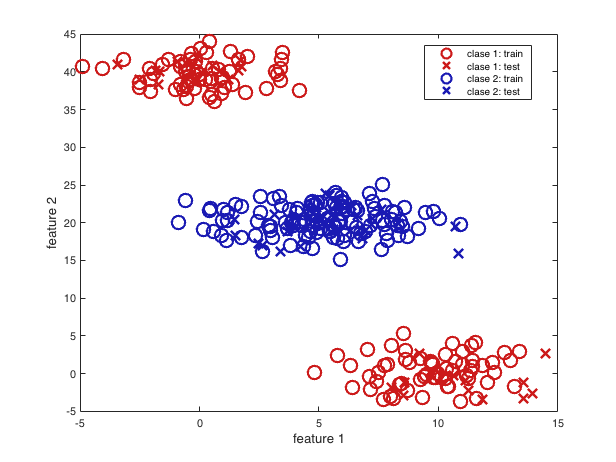

clear variables

patterns_per_class = 150;
ruido =2;

%% NO MODIFICAR ---------------------------------------------------------------
data_raw(:,1:patterns_per_class/2) = randn(2,patterns_per_class/2)*ruido+repmat([10; 0], 1, patterns_per_class/2);
data_raw(:,patterns_per_class/2+1:patterns_per_class) = randn(2,patterns_per_class/2)*ruido+repmat([0; 40], 1, patterns_per_class/2);
data_raw(:,patterns_per_class+1:patterns_per_class*2) = randn(2,patterns_per_class)*ruido+repmat([5; 20], 1, patterns_per_class);
X = [ones(1,size(data_raw,2));data_raw];
Y = [ones(1,patterns_per_class) ones(1,patterns_per_class)*0];

%% MODIFICAR ------------------------------------------------------------------
% Separamos los datos en training y validacion
train_frac = 0.8;
[Xtrain, Ytrain, Xval, Yval] = train_val_set(X,Y, train_frac);

%% NO MODIFICAR ---------------------------------------------------------------
% Visualizamos el conjunto de entrenamiento
figure
set(gcf,'name','conjunto de entrenamiento')
plot(Xtrain(2,Ytrain==1), Xtrain(3,Ytrain==1),'o','color',[.8 .1 .1], 'linestyle', 'none', 'markersize', 12 ,'linewidth',2)
hold on
plot(Xval(2,Yval==1),Xval(3,Yval==1),'x','color',[.8 .1 .1], 'linestyle', 'none', 'markersize', 12 ,'linewidth',2)
plot(Xtrain(2,Ytrain==0), Xtrain(3,Ytrain==0),'o','color',[.1 .1 .7], 'linestyle', 'none', 'markersize', 12,'linewidth',2)
plot(Xval(2,Yval==0), Xval(3,Yval==0),'x', 'color',[.1 .1 .7],'linestyle', 'none', 'markersize', 12,'linewidth',2)
set(gca, 'fontsize', 10)
xlabel('feature 1', 'fontsize', 12), ylabel('feature 2', 'fontsize', 12)
legend({'clase 1: train','clase 1: test', 'clase 2: train','clase 2: test'},'location','best')

**1.2.2 Aprendizaje**

Ahora vamos a modificar la función `learningNN_serial.m` para un algoritmo de clasificación. La única diferencia con el caso anterior de regresión es que ahora la neurona de la capa de salida aplicará la sigmoide a su función de activación.  Para esto crea una nueva función `gradientNN_class.m` a partir `gradientNN.m` para incluir la sigmoide en la capa de salida y la entropía cruzada. Encontrar los parámetros alpha, `hidden_units` y `max_iter` adecuados para lograr que el error baje al mínimo sin que haya overfitting. Crea la función `learningNN_class.m` copiando el código de `learningNN_serial.m.` Recuerda que ahora necesitas una nueva función para calcular el error (`GetError_class.m`), para incluir la sigmoide y la entropía cruzada, a la que llamarás desde `learningNN_class.m.`

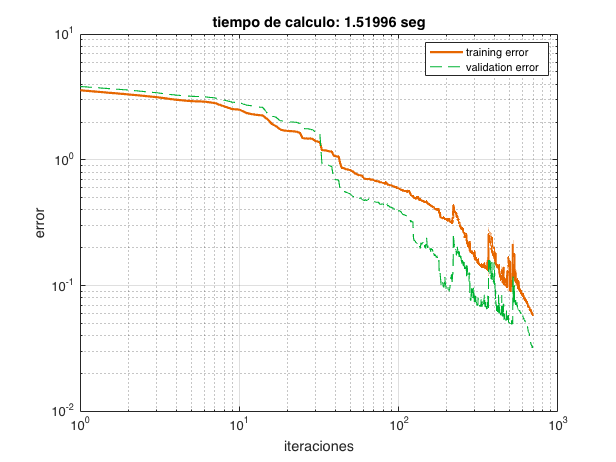

% Parametros de aprendizaje

hidden_units = 30;
max_iter = 700;
alpha = 0.01;

[E, E_val, W1, W2, ct] = learningNN_class( Xtrain, Ytrain, Xval, Yval, hidden_units, alpha, max_iter );

figure
%subplot(222)
plot(E, 'color', [.9 .4 0], 'linewidth', 2), hold on
plot(E_val, '--','color', [.0 .7 .2], 'linewidth', 1)
xlabel('iteraciones', 'fontsize', 10)
ylabel('error', 'fontsize', 10)
legend({'training error', 'validation error'}, 'fontsize', 10)
title(sprintf('tiempo de calculo: %g seg',ct))
set(gca, 'fontsize', 12,'yscale','log','xscale','log'), grid on

**1.2.3 Correct classification rate**

A continuación evaluamos el clasificador viendo cuántos patrones son clasificados correctamente. La variable `pred` (predicción) valdrá 0 o 1 dependiendo de si la clase predecida es la 1 o la 2. Para ello ponemos a 0 los valores de `y` que estén por debajo de 0.5 y a 1 los que estén por encima de 0.5.

%% Predecir la clasificación con los datos de entrenamiento

for p = 1:size(Xtrain,2)  % pattern loop       
    x = Xtrain(:,p); % entrada para la muestra p
    % calcula activacion para las neuronas ocultas:
    z_h = W1*x ;  % suma antes de la sigmoide
    a_h = sigmoid(z_h);  % activación de las neuronas ocultas
    a_h = [1; a_h];  % agrega la neurona cuyo valor es siempre igual a uno y que sirve de sesgo a la siguiente capa

    % calcula activacion de la neurona de salida:
    z_out = W2*a_h ;  % suma antes de la función de respuesta de la neurona de salida
    y(p) = sigmoid(z_out);  % calcula respuesta neurona de salida (regresion: identidad -- clasificacion: sigmoide logistica)  
end   

pred = y > 0.5; % ponemos a 0 los valores de y que estén por debajo de 0.5 y a 1 los que estén por encima de 0.5.
correct = sum(pred==Ytrain)/length(Ytrain);
display(['Porcentaje de classificaciones correctas en entrenamiento: ' num2str(correct)])

Porcentaje de classificaciones correctas en entrenamiento: 0.99167



class1 = sum(Ytrain==1);
class2 = sum(Ytrain==0);
cor_class1 = sum(pred(Ytrain==1)==1)/class1;
cor_class2 = sum(pred(Ytrain==0)==0)/class2;

%% Predecir la clasificación con los datos de validacion

for p = 1:size(Xval,2)  % pattern loop       
    x =  Xval(:,p); % entrada para la muestra p
    % calcula activacion para las neuronas ocultas:
    z_h = W1*x;  % suma antes de la sigmoide
    a_h = sigmoid(z_h);  % activación de las neuronas ocultas
    a_h = [1;a_h] ;  % agrega la neurona cuyo valor es siempre igual a uno y que sirve de sesgo a la siguiente capa

    % calcula activacion de la neurona de salida:
    z_out = W2*a_h;  % suma antes de la función de respuesta de la neurona de salida
    yval(p) = sigmoid(z_out) ;  % calcula respuesta neurona de salida (regresion: identidad -- clasificacion: sigmoide logistica)  
end   


pred = yval > 0.5;
correct = sum(pred==Yval)/length(Yval);
display(['Porcentaje de classificaciones correctas en validacion: ' num2str(correct)])

Porcentaje de classificaciones correctas en validacion: 1



class1_val = sum(Yval==1);
class2_val = sum(Yval==0);
cor_class1_val = sum(pred(Yval==1)==1)/class1_val;
cor_class2_val = sum(pred(Yval==0)==0)/class2_val;


**1.2.4 Medir el rendimiento del clasificador**

En este apartado vamos a visualizar la precisión del MLP para clasificar los datos de entrenamiento y los de validación. Para ello utilizaremos una función ya programada que calcula los márgenes de decisión, es decir, los límites que me determinan si una nueva muestra será etiquetada como clase 1 o como clase 2. 

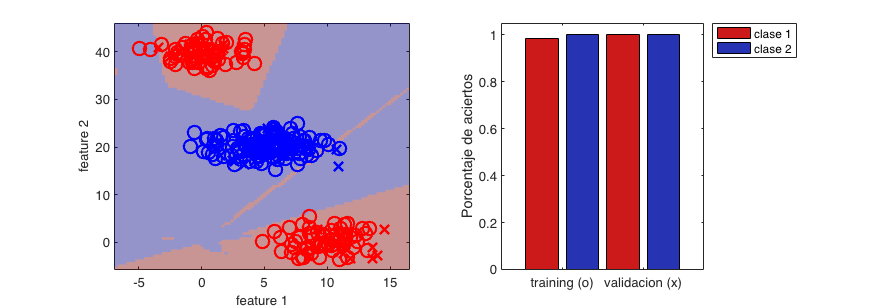

%% NO MODIFICAR -------------------------------------------------------------

plotOutputClass(Xtrain',Ytrain',Xval',Yval',data_raw',W1',W2',cor_class1,cor_class2,cor_class1_val,cor_class2_val)

**Comenta los resultados obtenidos:**

A mesura que augmenta el soroll, l'aprenentatge es complica molt i per tant no és capaç de classificar amb seguretat.

** Modifica el ruido inicial de los datos (subiéndolo o bajándolo ligeramente) para ver cómo de fácil o difícil resulta la clasificación. *

## 2. Datos reales

En este apartado simplemente aplicaremos las funciones implementadas para clasificar datos reales. Encuentra los parámetros adecuados y visualiza los resultados de clasificación. Copia de los apartados anteriores el código necesario para entrenar la red y para calcular los porcentajes de acierto. 

Estos datos tienen 4 filas de inputs (x). Recuerda que tienes que calcular 'W1_grad', cómo en la función gradientNN_class.m, tienes que multiplicar el delta de la capa oculta por cada input de los inputs 'x', en una nueva función modificada, gradientNN_class_real_data, dentro de la nueva función learningNN_class_real_data.

clear variables

%data = load('iris-versicolor.data');
data=load('iris-setosa.data');
%data=load('iris-virginica.data');


X = [ones(1,size(data,1)); data(:,1:4)'];
Y=data(:,5)';
% Separamos los datos en training y validacion
train_frac = 0.8;
[Xtrain, Ytrain, Xval, Yval] = train_val_set(X,Y, train_frac);
Ytrain(Ytrain==-1) = 0;
Yval(Yval==-1) = 0;

% aprendizaje

% Parametros de aprendizaje (igual que secio anterior)

hidden_units = 40;
max_iter = 700;
alpha = 0.01;

[E, E_val, W1, W2, ct] = learningNN_class_real_data( Xtrain, Ytrain, Xval, Yval, hidden_units, alpha, max_iter );



%% Predict classification with training data

for p = 1:size(Xtrain,2)  % pattern loop       
    x = Xtrain(:,p); % sample entry p %use Xtrain
    % Calculate activation for hidden neurons:
    z_h = W1*x;  % sum before the sigmoid %use W1
    a_h = sigmoid(z_h);  % activation of hidden neurons
    a_h = [1;a_h];  % add the neuron whose value is always equal to one and that serves as bias to the next layer

    % Calculate activation of the output neuron:
    z_out = W2*a_h ;  % sum before the output neuron response function %use W2
    y(p) = sigmoid(z_out);  % calculate output neuron response (regression: identity - classification: logistic sigmoid) 
end   

pred = y > 0.5; %use y
correct = sum(pred==Ytrain)/length(Ytrain);
display(['Porcentaje de classificaciones correctas en entrenamiento: ' num2str(correct)])

Porcentaje de classificaciones correctas en entrenamiento: 1



class1 = sum(Ytrain==1);
class2 = sum(Ytrain==0);
cor_class1 = sum(pred(Ytrain==1)==1)/class1;
cor_class2 = sum(pred(Ytrain==0)==0)/class2;

%% Predict classification with validation data

for p = 1:size(Xval,2)  % pattern loop       
    x = Xval(:,p); % sample entry p %use Xval
    % Calculate activation for hidden neurons:
    z_h = W1*x ;  % suma antes de la sigmoide %use WA
    a_h = sigmoid(z_h) ;  % activation of hidden neurons
    a_h = [1;a_h];  % add the neuron whose value is always equal to one and that serves as bias to the next layer

    % Calculate activation of the output neuron:
    z_out = W2*a_h ;  % sum before the output neuron response function %use W2
    yval(p) = sigmoid(z_out);  % calculate output neuron response (regression: identity - classification: logistic sigmoid) 
end   


pred = yval > 0.5; %use yval
correct = sum(pred==Yval)/length(Yval);
display(['Porcentaje de classificaciones correctas en validacion: ' num2str(correct)])

Porcentaje de classificaciones correctas en validacion: 1



class1_val = sum(Yval==1);
class2_val = sum(Yval==0);
cor_class1_val = sum(pred(Yval==1)==1)/class1_val;
cor_class2_val = sum(pred(Yval==0)==0)/class2_val;


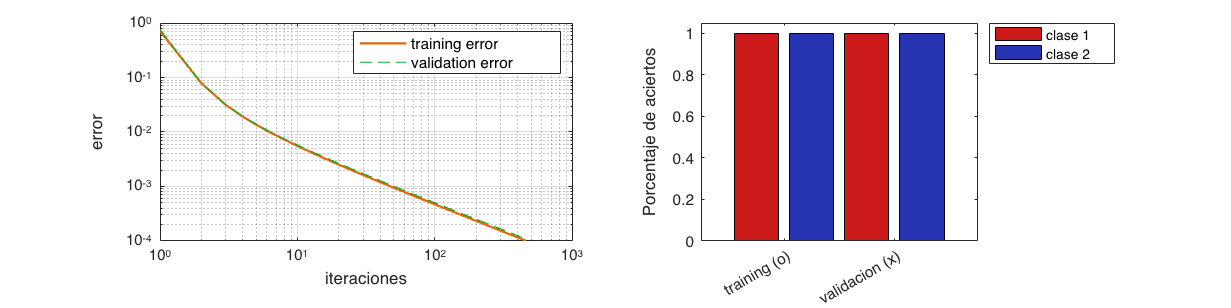

%% NO MODIFICAR -------------------------------------------------------------
figure
set(gcf,'units','normalized','position',[0,0.25,1,0.4])

subplot(121),cla
plot(E, 'color', [.9 .4 0], 'linewidth', 2), hold on
plot(E_val, '--','color', [.0 .7 .2], 'linewidth', 1)
xlabel('iteraciones', 'fontsize', 14)
ylabel('error', 'fontsize', 14)
legend({'training error', 'validation error'}, 'fontsize', 14)
set(gca, 'fontsize', 14,'yscale','log','xscale','log'), grid on

subplot(122),cla
bar(1, cor_class1,'facecolor', [.8 .1 .1])
hold on
bar(2, cor_class2,'facecolor', [.15 .2 .7])
bar(3, cor_class1_val,'facecolor', [.8 .1 .1])
bar(4, cor_class2_val, 'facecolor', [.15 .2 .7])
ylabel('Porcentaje de aciertos', 'fontsize', 14), ylim([0, 1.05])
legend('clase 1','clase 2','location','bestoutside'),xlim([0 5])
set(gca, 'fontsize', 14, 'XTick', [1.5,3.5],'XTickLabel',{'training (o)', 'validacion (x)'} )

**Prueba con los diferentes datos reales y comenta los resultados obtenidos:**

Amb les dades de iris-setosa el percentatge d'acert és 1 a training i validació, a iris-versicolor el percentatge d'acert és més gran que 0.95 pero no arriba a 1 i a iris-virginica és una mica més gran que la d'abans.

Per tant aquest MLP consegueix minimitzar molt més l'error i per tant predir molt millor les dades de iris-setosa.

**You can try to modify the initial noise of the data (by raising or lowering it slightly) to see how easy or difficult the classification is.*